# Quantum dynamics of one particle in 2D, of two interacting particles in 1D and Derivation of the Scattering Length

Temo Vekua

March 17, 2021

## Summary of live script 

This live script contains two computationally similar, but conceptually different problems: simulating dynamics of a quantum particle in two dimensions (2D) and simulating scattering of two interacting particles off each-other in 1D.

The first part of these notes is a mixture of quantum mechanics basics that lead to simulations of a single particle's wavefunction time evolution in a double-slit geometry. To reduce computational expense we consider a 2D case. Note that this is not an unrealistic situation; for example in experiments on ultra-cold quantum gases geometrically constrained systems (including 2D and 1D systems) are often realized.

The second part of the live script is dedicated to the basics of many-body quantum mechanics, leading to the simulation of the dynamics of two interacting particles in 1D. Appendix contains calculation of 1D scattering length for two-boson problem with contact delta function inter-particle interaction.

The material presented here is meant to follow [another lesson](https://serc.carleton.edu/matlab_computation2016/essays/160271.html) on simulating a single quantum particle's dynamics in 1D. 

## Single particle dynamics in 2D

One of the most impressive visualizations of the wave nature of quantum particles is the double-slit experiment. Thomas Young first performed such experiment in 1801 with light [1]. It took over 3 decades after the discovery of quantum mechanics for a similar experiment to be carried out with matter particles, with the first experiment using electrons  [2]. Today such experiments have been demonstrated for atoms and molecules as heavy as buckyballs $C_{60}$ [3].

We will start by reviewing the basics of quantum mechanics. We will also approximate the theoretical continuous model with a discrete space-time formulation that will be used for simulating a double-slit experiment. Then we will provide MATLAB code that shows different animated views of diffraction and interference of a quantum particle passing through a double-slit. In this way we will reverse engineer the seminal experiment visualizing the wave-like nature of electrons. 

Let us briefly define a glossary of terms:

**Diffraction **is the process that is characteristic to waves passing through a narrow aperture or across an edge and when the scattering object effectively becomes a secondary source of the propagating wave.

**Interference** is the process in which waves combine to reinforce (in-phase waves) or cancel (out-of-phase waves) each other, the amplitude of the resulting wave being equal to the sum of the amplitudes of the combining waves. 

### Introduction

The Schrodinger equation,


$$(1) \quad i\hbar \frac{d}{dt} |\psi(t)\rangle = \hat H |\psi (t)\rangle,$$


governs the evolution of a pure quantum state of a particle (or many-particle system) in time. In Eq.(1) $\hbar$ is the reduced Planck's constant, $\hat H$ is the Hamilton operator and $|\psi(t)\rangle$ is a ket vector encoding the quantum state at time $t$. 

### Single particle in one (discrete) dimension: warm-up case

For carrying out numerical simulations we first need to discretize space (and later time for studying dynamics). We will start by the simplest 1D case and determine matrix representation of $\hat x$ and $\hat p$ in real-space basis, after discretizing space (a segment of length $L$) in $N$ equally spaced points $x_j=(j-1)L/(N-1)$, where $j=1,2,...N$. Hence $x_1=0,x_2=L/(N-1),...,x_N=L$.

Basis vectors $|x_j\rangle$ (normalized eigenvectors of $\hat x$ operator) are represented as columns with all entries equal to zeros, except of $1$ at the j-th position (denoted as $1_j$),

$|x_j \rangle\to \left( \begin{array}{c}  
 0\\ 
0\\
\cdots\\
1_j\\
\cdots\\
0_N  
\end{array} \right)$.

One can check that these states form the complete basis, since resolution of identity holds:


$$\sum^N_{j=1} |x_j \rangle \langle x_j|=1_{N,N}.$$


In these notes the Schrodinger picture is adopted, where state vector $|\psi \,\rangle$ evolves in time according to Eq. (1), whereas operators (corresponding to observables), as well as their eigenbasis of eigenvectors $\hat x= \sum_j |x_j \rangle x_j \langle x_j|$, are time independent. Note $\hat x$ is represented by a diagonal $N\times N$ matrix in real-space basis, 

$\hat x \to  \left( \begin{array} {llllll}
 x_1 \quad \quad & 0 \quad \quad & 0\quad \quad & \cdots\quad \quad & 0 \quad \quad&0  \\
0 & x_2 & 0 & \cdots & 0&0    \\
0 & 0 & x_3 & \cdots & 0&0   \\
\vdots & \vdots & \vdots & \vdots & \vdots & \vdots\\
0 & 0 & 0 & \cdots & x_{N-1}&0    \\
0 & 0 & 0 &\cdots & 0 & x_N    \\
\end{array} \right)
$.

A ket-vector $|\psi \rangle$, representing a pure quantum state, in the real-space basis is stored as an $N$-element column vector made of (in general complex) numbers $\psi (x_j)=\langle x_j|\psi \rangle$ at $j$-th position:

 $(2) \quad  | \psi \rangle =\sum^N_{j=1} \psi (x_j)|x_j\rangle\to  \psi(x_1) \left( 
 \begin{array} {c}
1\\ 
0\\
\vdots\\
0
\end{array} \right)+ \psi(x_2) \left( 
 \begin{array} {c}
0\\ 
1\\
\vdots\\
0
\end{array} \right)+
\cdots= \left( \begin{array}{c}  
\psi (x_1)\\ 
\psi (x_2)\\
\vdots\\
\psi (x_N)\\
\end{array} \right)$.

A differential operator $\hat{D}$ acting on $|\psi \rangle$ (gradient, Laplacian, etc.) is represented by a $N\times N$ matrix $D$ that acts on columns, such as those in the right-most-side of Eq. (2). For example when acting with momentum operator on the states we have:


$$\hat p | \psi  \rangle =\hat p  \sum^N_{j=1} |x_j\rangle \langle x_{j} |\psi  \rangle   =  \hat p (..., \psi (x_{j-1}), \psi (x_j), \psi (x_{j+1}),...)^T= -i\hbar(...,\psi '(x_{j-1}), \psi'(x_j), \psi'(x_{j+1}),...)^T,$$


where superscript $T$ indicates transpose (we remind that a transpose of a row is a column) and $\psi'(x_j)$ is the value of (1D) gradient of function $\psi$ (1D gradient of a scalar function is also a scalar  function) at point $x_j$,$\psi'(x_j)=\frac{\psi (x_j+\Delta x) - \psi(x_j-\Delta x)}{2\Delta x}=\frac{\psi (x_{j+1}) - \psi(x_{j-1})}{2\Delta x}$.

Hence, the matrix corresponding to $\hat p$ (discussing bulk and neglecting boundaries) in discrete real-space representation will look:

$\hat p \to  \left( \begin{array}{cccccc}
 0& -\frac{i \hbar }{2\Delta x} & 0& 0 & 0&0  \\
\frac{i \hbar }{2\Delta x}& 0 & -\frac{i \hbar}{2\Delta x} & 0 & 0&0    \\
0 & \frac{i \hbar}{2\Delta x} & 0 & -\frac{i \hbar}{2\Delta x} & 0&0   \\
0 & 0 & \frac{i \hbar}{2\Delta x}& 0 &-\frac{i\hbar}{2\Delta x}&0   \\
0 & 0 & 0 & \frac{i \hbar}{2\Delta x} & 0&-\frac{i \hbar}{2\Delta x}    \\
0 & 0 & 0 &0 & \frac{i \hbar}{2\Delta x} & 0    \\
\end{array} \right)
$.

If instead we approximate: $\psi'(x_j)=\frac{\psi (x_{j+1}) - \psi(x_{j})}{\Delta x}$, then matrix corresponding to the operator $\hat p$ will not be Hermitian.

A note on canonical commutation relation is in order here. Commutator of two finite-dimensional matrices must be traceless matrix (since under trace one can permute finite-dimensional matrices without affecting the result, $tr (AB)=tr(BA)\to tr[A,B]=0$). Hence we need to interpret the canonical commutation relation: $[\hat x,\hat p]=i\hbar$, when discretizing space and representing observables such as coordinate and momentum by finite dimensional matrices. Let us check numerically canonical commutation relation. 

cwd(); % change to the directory where Live script is located
L = 2;                   % interval length in each direction
N = 10;                  % number of coordinate points in each direction
x = linspace(0, L, N).'; % coordinate column vector in x direction
dx = x(2) - x(1);        % coordinate step 
hbar=1;
p  = hbar*(diag(-1i*ones(N-1,1),1)+  diag(1i*ones(N-1,1),-1) )/ (2*dx);
x = diag(x); % coordinate operator
x*p-p*x      % canonical commutation relations

ans =   0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.500000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i
  0.000000000000000 + 0.500000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.500000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i
  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.500000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.500000000000000i  0.000000000000000 + 0.00000000

As we see, instead of $i\hbar \cdot 1_{N,N}$, for commutation relation between finite-dimensional representation of $\hat x$ and $\hat p$ we obtained the following matrix: 

$[\hat x, \hat p]$ $\to i\hbar \left( \begin{array} {llllll}
 0 \quad \quad & \frac{1}{2} \quad \quad & 0\quad \quad & 0\quad \quad & 0 \quad \quad&0  \\
\frac{1}{2} & 0 & \frac{1}{2} & 0 & 0&0    \\
0 & \frac{1}{2} & 0 & \frac{1}{2} & 0&0   \\
0 & 0 & \frac{1}{2}& 0 &\frac{1}{2}&0   \\
0 & 0 & 0 & \frac{1}{2} & 0&\frac{1}{2}    \\
0 & 0 & 0 &0 & \frac{1}{2} & 0    \\
\end{array} \right)
$.

Acting on the continuous functions (columns) with the above matrix and with $i\hbar \cdot 1_{N,N}$ matrix produce identical results for $\Delta x \to 0$. Indeed it will be numerically hard to distinguish whether at the $j$-th position of the  column ket-vector there will be $i\hbar [\psi (x_{j-1})+\psi(x_{j+1})]/2$, or $i\hbar \psi (x_j)$ for continuous functions.  

### Stationary Problems

For time-independent Hamiltonian, the Schrodinger Eq. (1) is solved as: 

$|\psi (t) \rangle = e^{-i \hat H t / \hbar}|\psi(0)\rangle$.

If at $t=0$ a state of the system coincides with one of the energy eigenstates $|\psi (0) \rangle = |\psi_E  \rangle$, then, at time $t$, we will have:

$(3) \quad |\psi (t) \rangle = |\psi_E\rangle \, e^{-i E t / \hbar}$.

Hence, if a state of a quantum  system at $t=0$ is one of the eigenstates of energy operator, it will evolve in time with a multiplicative phase factor and particle density in such state will be time independent. To observe non-trivial time evolution of particle densities, initial state must not be eigenstate of Hamiltonian.

Plugging $|\psi(t)\rangle$ from Eq. (3) into Eq. (1) and canceling exponential phase factors from both sides of the resulting equation, we obtain for energy eigenstate $|\psi_E\rangle$ the time-independent Schrodinger equation


$$(4) \quad \hat H\, |\psi_E\rangle = E\,|\psi_E\rangle.$$


Equations such as Eq. (4) in mathematics are known as eigenvalue equations for differential operators. In Eq. (4) we are solving simultaneously for the eigenvalues $E$ and eigenvectors $|\psi_E\rangle$ of $\hat H$. The command 

`[V,E] = eig(H)` 

does precisely this: it generates two matrices. First matrix $V$ has as its columns the eigenvectors $|\psi_E\rangle$ (which may not always be normalized to unity). The second matrix $E$ is a diagonal matrix with the eigenvalues $E_i$ corresponding to the eigenvectors $|\psi_{E_i}\rangle$ placed along the central diagonal. If columns of V are normalized eigenstates (if they are not returned as such, we can normalize them), then the following relation holds between matrices E, V, and H (due to the fact that matrix corresponding to Hamiltonian is a Hermitian matrix): 

`E=V'*H*V,` 

where prime means hermit conjugation (transposition & complex conjugation of  a matrix).

We can use the command `E = diag(E)` to convert diagonal matrix E into a column vector E (or vice versa). 

Usually quantum mechanical Hamiltonian is made of kinetic energy and potential energy parts $\hat H=\hat H_K+\hat V$, where $\hat H_K=\hat p^2/(2m)$. For kinetic energy part we have:

$\hat H_K | \psi \rangle =\hat H_K\sum_j |x_j\rangle \langle x_j  | \psi \rangle =\hat H_K (..., \psi(x_{j-1}), \psi(x_j), \psi(x_{j+1}),...)^T= -\frac{\hbar^2}{2m}(...,\psi''(x_{j-1}), \psi''(x_j), \psi''(x_{j+1}),...)^T$, 

where $\psi''(x_j)$ is value of a Laplacian of$f$ (Laplacian of function is also a function) at point $x_j$, for which we will use three-point discrete Laplacian: 

$\psi''(x_j)=\frac{\psi(x_{j+1}) +\psi(x_{j-1}) -2\psi(x_j)}{(\Delta x)^2}$.

Note that we could have squared the matrix corresponding to $\hat p$ and multiplied it by $1/(2m)$ for obtaining matrix corresponding to $\hat H_K$, but that yields less accurate discrete approximation of Laplacian.  

If we want wavefunctions to vanish at the boundary (infinite wall) after time evolution as well, we can impose large potential energy at the boundary (that we will do in most of our simulations), or modify matrix corresponding to Laplacian at the boundary points in the following way:

$\hat H_K \to   -\frac{\hbar^2}{2m} \Delta_x = -\frac{\hbar^2}{2m} \left( \begin{array}{cccccc}
0&    0& 0 & 0& \cdots&0 &0&0 \\
0& - \frac{2}{(\Delta x)^2} & \frac{1}{(\Delta x)^2} & 0 &\cdots   &0 &0&0\\
0&  \frac{1}{(\Delta x)^2} &  -\frac{2}{(\Delta x)^2} & \frac{1}{(\Delta x)^2} &\cdots&0 &0&0\\
\vdots& \vdots & \vdots & \vdots & \vdots & \vdots &\vdots&\vdots\\
0&  0&0 &\cdots&\frac{1}{(\Delta x)^2} &  -\frac{2}{(\Delta x)^2} & \frac{1}{(\Delta x)^2} &0\\
0& 0 & 0 &\cdots&0& \frac{1}{(\Delta x)^2}& -\frac{2}{(\Delta x)^2} &   0\\
0 &0 &0  &\cdots&0 &0 &0 &0
\end{array} \right)
$.

This modification guarantees that after time evolution $\psi(x_1,t)=0$ and $\psi(x_N,t)=0$ if  at initial time $\psi(x_1)=0$ and $\psi(x_N)=0$, however it comes with a price to pay: it brings unphysical zero energy states that are localized at the boundaries. We should remember to filter out these states. 

Potential part of Hamiltonian (if it contains only dependence on coordinates and not on momenta) is described by a diagonal matrix in real-space basis:

$\hat V \to  \left( \begin{array} {c c c c c c }
 V(x_1)  & 0  & 0  &\cdots & 0  &0  \\
0 & V(x_2) & 0  &\cdots &0   &0 \\
0 & 0 & V(x_3)  &\cdots &0  &0  \\
\vdots &  \vdots & \vdots &\vdots &\vdots  & \vdots\\
0 & 0 & 0   &\cdots& V(x_{N-1})&0    \\
0 & 0 & 0 &\cdots& 0 & V(x_N)    \\
\end{array} \right)
$.

In most of simulations we will assume $V(x_1)=V(x_N) \gg1$ to force vanishing of the wavefunction at the boundaries energetically.

### From 1D to 2D: `kron` & `meshgrid` functions

Passing from 1D to higher dimensions needs explanations for the clarity of subsequent simulations. Real-space basis vectors in 2D (2D space is approximated by $N$ discrete points along each dimension, hence by a square grid with $N^2$ points) can be represented as column vectors with $N^2$ elements, all zeros, except of a single $1$ at $k$-th position of the column, where $k=(i-1)N+j$:

$(5) \quad  | \vec  r\rangle = | x_i, y_j \rangle =   | x_i\rangle \otimes | y_j \rangle$.

One can easily check hat resolution of identity holds: $\sum_{i,j}  |x_i,y_j\rangle \langle x_i,y_j|=1_{N^2,N^2}$, hence any state defined on $N^2$ grid can be decomposed into them as:

$|\psi \rangle= \sum^N_{(i,j)=1}     |x_i, y_j\rangle \langle x_i,y_j |\psi \rangle= \sum_{i,j}    \psi(x_i,y_j) |x_i, y_j\rangle$.

Hence to a state vector $|\psi \rangle$ corresponds the following column with $N^2$ elements:

$| \psi \rangle \to \left( \begin{array}{c}  
 \psi(x_1, y_1)\\ 
\psi (x_1,y_2)\\
\cdots\\
\psi(x_1,y_N)\\
\psi(x_2,y_1)\\
\cdots\\
\psi(x_N,y_N)  
\end{array} \right)$.

First we introduce a column vector encoding discretized x axes (similar to 1D case, a discretized segment from $0$ to $L$ with $N$ equally spaced points):

`x = linspace(0,L,N).'`

In 1D case this column `x` encodes a state that is a superposition of all real-space basis vectors with amplitudes given by their coordinates: $\sum_i x_i |x_i\rangle$. Function applied to a column` x, psi(x)` is a column corresponding to a state given in Eq. (2). Now, let's introduce column y for the second discrete dimension:

`y = linspace(0,L,N).'`

As we see in this case` y=x `and hence for Laplacian matrices we have $\Delta_x=\Delta_y$`.`

The following matrix will correspond to the kinetic energy part of Hamiltonian in 2D:

$\hat H_K = -\frac{\hbar^2}{2m} \left( \Delta_x\otimes  1_{N,N}+1_{N,N}\otimes \Delta_x \right)$.

Any state can be written as:

$|\psi \rangle= \sum^N_{i,j}    \psi(x_i,y_j) |x_i, y_j\rangle= \sum^N_{i,j}    \psi(x_i,y_j) |x_i\rangle \otimes | y_j\rangle=\sum^{N^2}_{k=1}   \psi(k) |k\rangle$, where $k=(i-1)N+j$ and $|k\rangle$ is a column with $N^2$ elements with all zeros, except of 1 at $k$-th position. To any 2D point $(x_i,y_j)$ a unique $k$ value corresponds and vice versa, to each of the values $k=1,2,3,...N^2$ a unique 2D point corresponds. This is a one-dimensional column-major enumeration of a 2D grid as sketched in the image below for $N=4$.

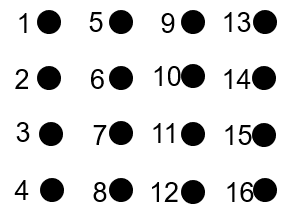  $1\to (x_1,y_1)$, $2\ \to (x_1,y_2)$,... $16\to  (x_4,y_4)$

We will use MATLAB's `kron` function to implement a direct product.

To a state $\sum^{N^2}_{k=1}   \psi(k) |k\rangle =(\psi(1),\psi(2),...\psi(N^2))^T$ (with $N^2$ elements) corresponds a following column:

 $\sum^{N^2}_{k=1}   \psi(k) |k\rangle\to$`psi(kron(x,ones(N,1)), kron(ones(N,1),y)).`

For example a state $|\psi\rangle=\sum_{i,j}\psi(x_i,y_j)|x_i,y_j\rangle=\sum_{i,j}e^{-x_i^2-y_j^2}|x_i,y_j\rangle$ may be stored as a column vector with $N^2$ elements: 

`(*)   psi = exp( -kron(x,ones(N,1)).^2 -kron(ones(N,1),y).^2 )`

Alternatively, we can reshape this $N^2$ element column into $N$`x`$N$ square matrix by `psi=reshape(psi,N,N)` and instead deal with matrices, without loosing any information. The latter encoding of state is especially convenient when used together with a `meshgrid` function

x = sym('x', [4 1]) % for N=4 define symbolic variables for the clarity of meshgrid function

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4} \end{array}\right)$$

y = sym('y', [4 1])

$$y = \left(\begin{array}{c} y_{1}\\ y_{2}\\ y_{3}\\ y_{4} \end{array}\right)$$

[X,Y] = meshgrid(x,y)

$$X = \left(\begin{array}{cccc} x_{1} & x_{2} & x_{3} & x_{4}\\ x_{1} & x_{2} & x_{3} & x_{4}\\ x_{1} & x_{2} & x_{3} & x_{4}\\ x_{1} & x_{2} & x_{3} & x_{4} \end{array}\right)$$

$$Y = \left(\begin{array}{cccc} y_{1} & y_{1} & y_{1} & y_{1}\\ y_{2} & y_{2} & y_{2} & y_{2}\\ y_{3} & y_{3} & y_{3} & y_{3}\\ y_{4} & y_{4} & y_{4} & y_{4} \end{array}\right)$$

psi = exp(-X.^2 - Y.^2)

$$psi = \left(\begin{array}{cccc} {\mathrm{e}}^{-{x_{1}}^{2}-{y_{1}}^{2}} & {\mathrm{e}}^{-{x_{2}}^{2}-{y_{1}}^{2}} & {\mathrm{e}}^{-{x_{3}}^{2}-{y_{1}}^{2}} & {\mathrm{e}}^{-{x_{4}}^{2}-{y_{1}}^{2}}\\ {\mathrm{e}}^{-{x_{1}}^{2}-{y_{2}}^{2}} & {\mathrm{e}}^{-{x_{2}}^{2}-{y_{2}}^{2}} & {\mathrm{e}}^{-{x_{3}}^{2}-{y_{2}}^{2}} & {\mathrm{e}}^{-{x_{4}}^{2}-{y_{2}}^{2}}\\ {\mathrm{e}}^{-{x_{1}}^{2}-{y_{3}}^{2}} & {\mathrm{e}}^{-{x_{2}}^{2}-{y_{3}}^{2}} & {\mathrm{e}}^{-{x_{3}}^{2}-{y_{3}}^{2}} & {\mathrm{e}}^{-{x_{4}}^{2}-{y_{3}}^{2}}\\ {\mathrm{e}}^{-{x_{1}}^{2}-{y_{4}}^{2}} & {\mathrm{e}}^{-{x_{2}}^{2}-{y_{4}}^{2}} & {\mathrm{e}}^{-{x_{3}}^{2}-{y_{4}}^{2}} & {\mathrm{e}}^{-{x_{4}}^{2}-{y_{4}}^{2}} \end{array}\right)$$

psi=psi(:)   % render as a 1D columnar vector

$$psi = \left(\begin{array}{c} {\mathrm{e}}^{-{x_{1}}^{2}-{y_{1}}^{2}}\\ {\mathrm{e}}^{-{x_{1}}^{2}-{y_{2}}^{2}}\\ {\mathrm{e}}^{-{x_{1}}^{2}-{y_{3}}^{2}}\\ {\mathrm{e}}^{-{x_{1}}^{2}-{y_{4}}^{2}}\\ {\mathrm{e}}^{-{x_{2}}^{2}-{y_{1}}^{2}}\\ {\mathrm{e}}^{-{x_{2}}^{2}-{y_{2}}^{2}}\\ {\mathrm{e}}^{-{x_{2}}^{2}-{y_{3}}^{2}}\\ {\mathrm{e}}^{-{x_{2}}^{2}-{y_{4}}^{2}}\\ {\mathrm{e}}^{-{x_{3}}^{2}-{y_{1}}^{2}}\\ {\mathrm{e}}^{-{x_{3}}^{2}-{y_{2}}^{2}}\\ {\mathrm{e}}^{-{x_{3}}^{2}-{y_{3}}^{2}}\\ {\mathrm{e}}^{-{x_{3}}^{2}-{y_{4}}^{2}}\\ {\mathrm{e}}^{-{x_{4}}^{2}-{y_{1}}^{2}}\\ {\mathrm{e}}^{-{x_{4}}^{2}-{y_{2}}^{2}}\\ {\mathrm{e}}^{-{x_{4}}^{2}-{y_{3}}^{2}}\\ {\mathrm{e}}^{-{x_{4}}^{2}-{y_{4}}^{2}} \end{array}\right)$$

Using these $N$`x`$N$ matrices X and Y, we can encode the above state vector in Eq. (*) in $N$x$N$ square matrix, thus avoiding wordy explicit direct products:

`psi = exp(-X.^2 - Y.^2)`

which, visually is much more appealing: it is less wordy and similar to what we write on paper.

After this, when we need, we can reshape `psi` back to a column by `psi=psi(:);`

Let's now study eigenstates of a single particle Hamiltonian in 2D, when particle is localized in a finite square ($L$x$L$) and in L-shaped planar geometry.

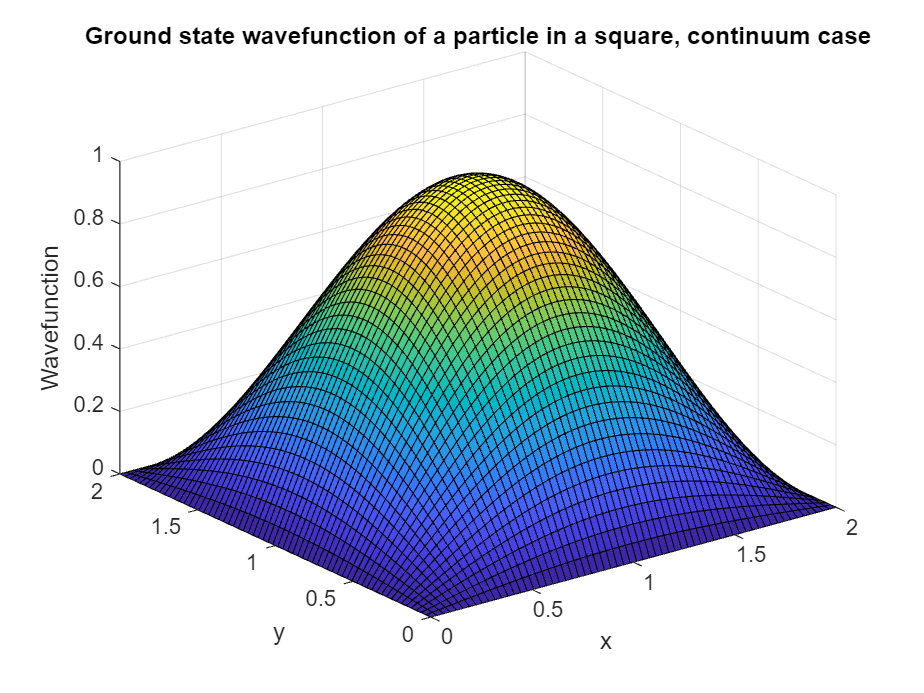

L = 2;                   % Interval Length in each direction
N = 64;                  % Number of coordinate points in each direction
x = linspace(0, L, N).'; % Coordinate column vector in x direction
dx = x(2) - x(1);        % Coordinate step 

e    = ones(N,1);        % a column of N elements made of 1-s 
Lap_x  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;  % sparse matrix needs much less memory to be stored
% and operations on sparse matrices are fast
% spdiags creates sparse diagonal matrix and places column -2*e on a main
% diagonal (indicated by 0) and columns e on a lower (-1) and upper (1) diagonals of NxN matrix
% Lap_x(1,   1) = 0; Lap_x(  1, 2) = 0; Lap_x(2, 1) = 0;
% Lap_x(N, N-1) = 0; Lap_x(N-1, N) = 0; Lap_x(N, N) = 0; 

V=kron(heaviside(x-L/2),heaviside(x-L/2));  % step potential in the upper right quarter (for restricting particle to L-shaped region)

V_add=kron(heaviside(x-L)+heaviside(0-x),e)+kron(e,heaviside(x-L)+heaviside(0-x));
% V_add is additional potential at the boundary of the square region, to
% force wavefunction vanish there energetically

%V_harm =sparse((kron((x-L/2).^2,e) +  kron(e,(x-L/2).^2))); % example of additional here harmonic confinement 

% Total Hamiltonian where hbar=1 and m=1.
hbar = 1; 
m = 1; 
H_K = -(1/2)*(hbar^2/m)*(kron(Lap_x,speye(N))+kron(speye(N),Lap_x));
H_K=H_K+10000*sparse(diag(V_add));
H_V=1000*sparse(diag(V));
H=H_K+H_V;

[X,Y] = meshgrid(x);
surf( X,Y, 2/L* sin(pi*X/L).*sin(pi*Y/L))  % true ground state for continuum problem of particle restricted to a square
axis([0 L 0 L]);
% E_0=h_bar^2*pi^2/ (m*L^2), for L=2, m=1, h_bar=1 E_0=pi^2/4=2.4674
   xlabel('x')
   ylabel('y')
   zlabel('Wavefunction')
   title('Ground state wavefunction of a particle in a square, continuum case')

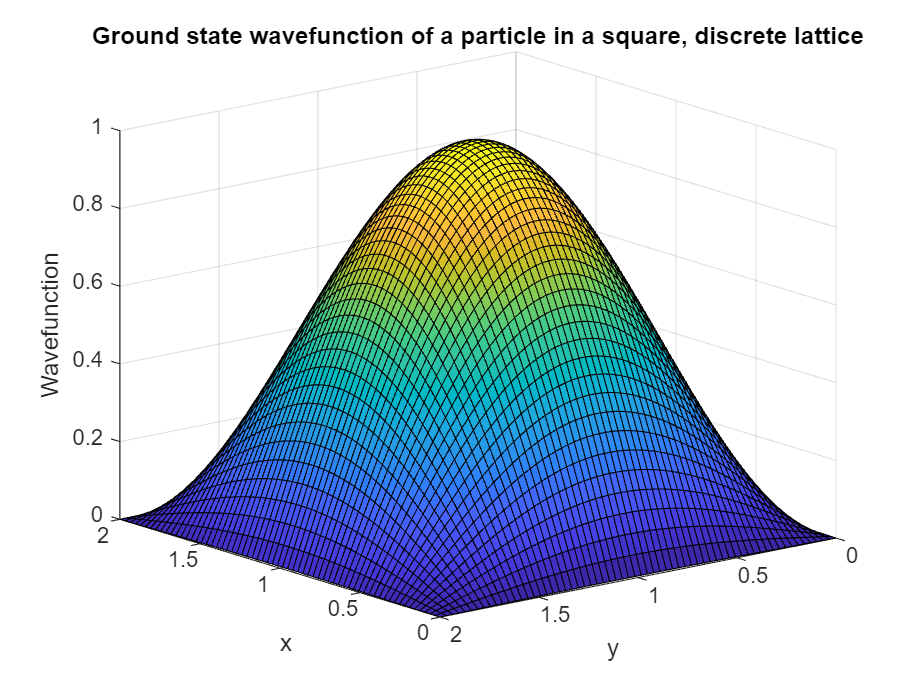


% Solve for eigenvector matrix Vec and eigenvalue matrix E_K of H_K.
[Vec,E_K] = eigs(sparse(H_K),5,'smallestreal'); % find eigs.
[E_K,ind] = sort(diag(E_K));       % convert E_K to a column vector and sort low to high.
Vec = Vec(:,ind);                  % rearrange corresponding eigenvectors.


surf(X,Y,reshape(Vec(:,1)/dx,N,N))  
axis([0 L 0 L]);
   xlabel('x')
   ylabel('y')
   zlabel('Wavefunction')
   title('Ground state wavefunction of a particle in a square, discrete lattice')

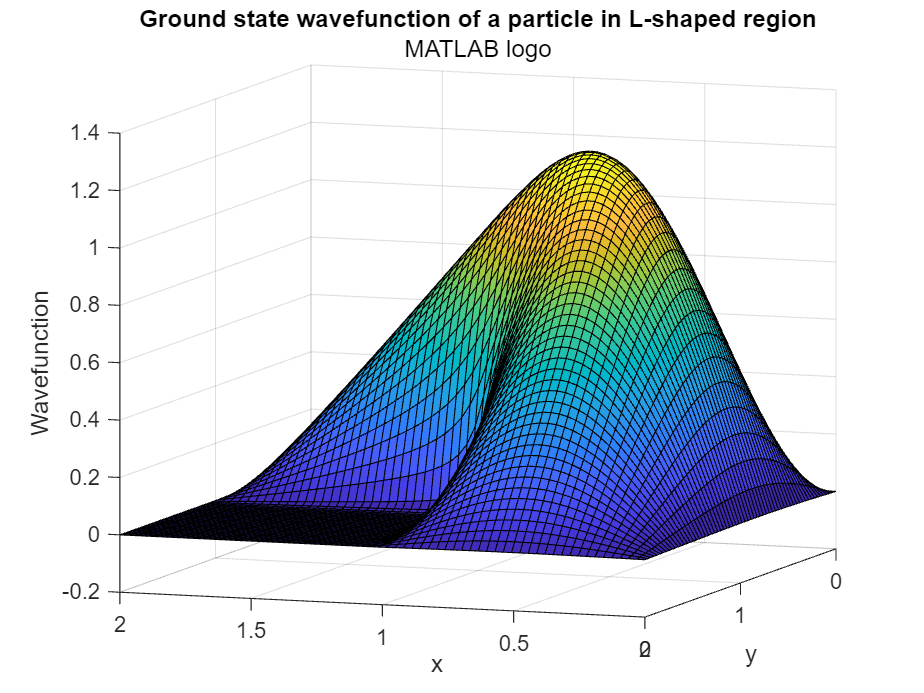


% Solve for eigenvector matrix Vec and eigenvalue matrix E of H.
[Vec,E] = eigs(sparse(H),5,'smallestreal'); 
[~,ind] = sort(diag(E));       
Vec = Vec(:,ind);              

surf(X,Y,reshape(Vec(:,1)/dx,N,N))  
axis([0 L 0 L]);
   xlabel('x')
   ylabel('y')
   zlabel('Wavefunction')
   %zlim([0 1.5])
   title('Ground state wavefunction of a particle in L-shaped region')
   subtitle('MATLAB logo')   
   view([-160 9])

### `Simulating double-slit experiment`

Here we will simulate two-dimensional dynamics of a single particle that is initially described by a Gaussian wavepacket launched with a nonzero momentum and scattered from the double slit geometry.

L = 8*pi; % Interval length along each direction
N = 64;   % No of points along each direction, 2D grid will have NxN points

x = linspace(0,L,N).';
dx = x(2) - x(1);          
% Barrier potentials that mimic double-slit geometry are V1, V2 and V3

c1="open"

c1 = "open"

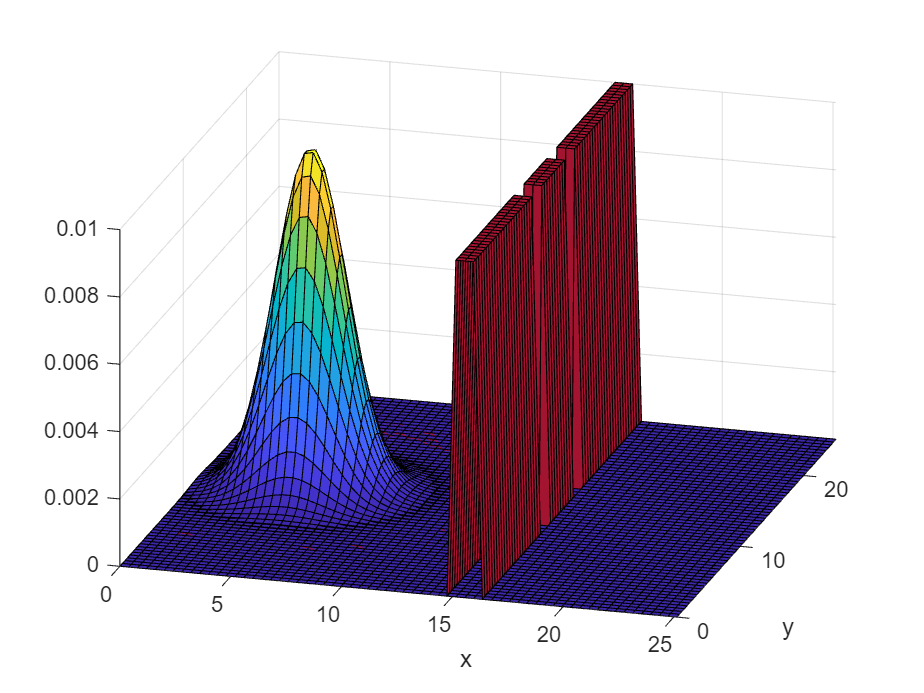


V1x=heaviside(x-3*L/5)-heaviside(x-(3*L/5+1));
V1y=heaviside(x-(2*L/3-1));
%V1y=heaviside(x-(L/2+2)); % uncomment this line to close upper slit and comment out to open
V1=kron(V1x,V1y);
V1=reshape(V1,N,N);

V2x=heaviside(x-3*L/5)-heaviside(x-(3*L/5+1)); 
V2y=heaviside(x-L/3-2)-heaviside(x-(L/2+2));
V2=kron(V2x,V2y);
V2=reshape(V2,N,N);

V3x=heaviside(x-3*L/5)-heaviside(x-(3*L/5+1));
V3y=heaviside(L/3+1-x); 
% V3y=heaviside(L/3+2-x); % uncomment this line to close upper slit and comment out to open
V3=kron(V3x,V3y);
V3=reshape(V3,N,N);
V=V1+V2+V3;

% uncomment lines below to observe a case when slits are further away from each other
% V1x=-heaviside(x-3*L/5)+heaviside(x-(3*L/5+1));
% V1y=-heaviside(x-(5*L/6-1));
% %V1y=-heaviside(x-(L/2+2)); %only one slit open case
% V1=kron(V1x,V1y);
% V1=reshape(V1,N,N);
% 
% V2x=heaviside(x-3*L/5)-heaviside(x-(3*L/5+1)); 
% V2y=-heaviside(x-5*L/6+2)+heaviside(x-(L/4));
% V2=kron(V2x,V2y);
% V2=reshape(V2,N,N);
% 
% V3x=heaviside(x-3*L/5)-heaviside(x-(3*L/5+1));
% V3y=heaviside(L/4-1-x);
% V3=kron(V3x,V3y);
% V3=reshape(V3,N,N);
% V=V1+V2+V3;



screen_x=heaviside(x-7*L/8)-heaviside(x-(7*L/8+0.5)); % for plotting screen where particle is detected
screen_y=heaviside(L-x);
screen=kron(screen_x,screen_y);
screen=reshape(screen,N,N);

dk = 2*pi/L;              % Momentum step
km = N*dk;                % Momentum limit
kx = linspace(0,km,N).';  % Momentum x column vector


[X,Y]=meshgrid(x);
psi = exp(-0.1*( (X-L/5).^2 +(Y-L/2).^2 )).*exp(1i*kx(12)*X);
%Launched Gaussian wavepacket. Initial wavefunction in NxN matrix form

psi = psi(:) / sqrt(psi(:)' * psi(:) ); % convert to a normalized column

Lap_x = (diag(ones((N-1),1),-1) - 2*diag(ones(N,1),0) + diag(ones((N-1),1), 1)) / (dx^2);

Height=40;

H   = -(1/2)*(kron(Lap_x,eye(N))+kron(eye(N),Lap_x))+Height*diag(V(:));
H = single(H);
% Parameters for computing psi(x,t) at different times 0 < t < TF.
NT = 120;                % No. of time steps.
TF =7;
t  = linspace(0,TF,NT); % time vector
dt = t(2) - t(1);       % time step
hbar = 1;

% time displacement operator
Evolution_Operator = expm(-1i * H * dt / hbar); % matrix exponentiation, expensive step

rho = conj(psi) .* psi; % rho(x,t) is a column vector
surf(X,Y,0.01*V,'FaceColor', '[0.6350, 0.0780, 0.1840]');
hold on
surf(X,Y,reshape(rho,N,N));
hold off
view([20.0000 -70.00000 40])
axis([0 L 0 L 0 0.01]);
xlabel('x');
ylabel('y'); 

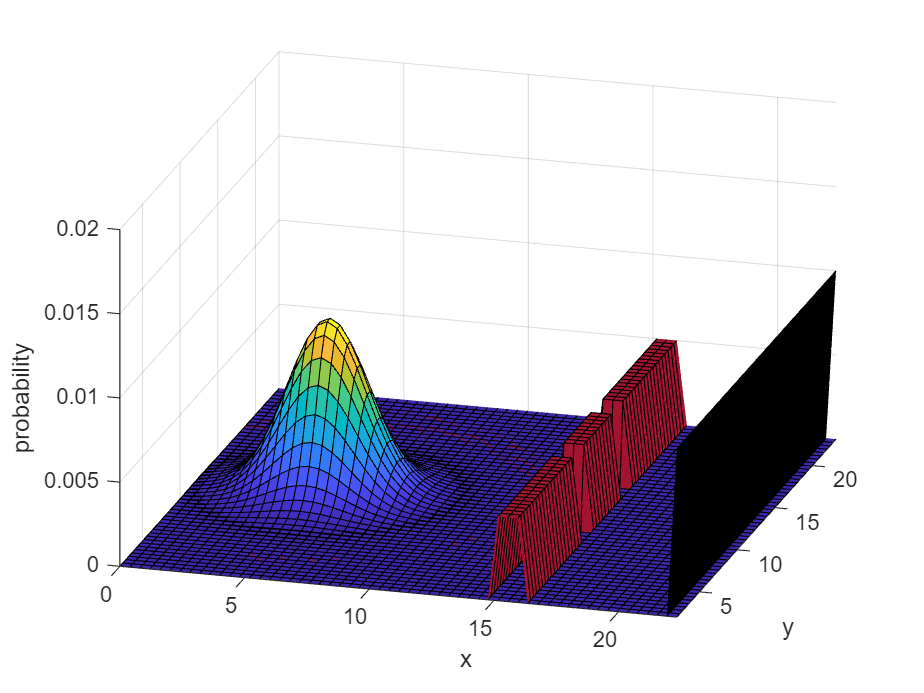

gca.ZAxis.Visible = 'off';


surf(X,Y,0.01*screen, 'Facecolor','black');
hold on
surf(X,Y,0.005*V, 'Facecolor','[0.6350, 0.0780, 0.1840]');
surfPlot=surf(X,Y,reshape(rho,N,N));
view([20.0000 -70.00000 40]) % 3Dview
    % view([0 90])  % 2D view
    axis([0 8*L/9 2 L-2 0 0.02]);
    xlabel('x');
    ylabel('y');
    zlabel('probability')
for jj = 1:NT % Time index for loop
    psi = Evolution_Operator*psi;   % Calculate psi(t+\Delta t) from psi(t)
    rho = conj(psi).* psi; % rho(x,t), probability density 
    surfPlot.ZData=reshape(rho,N,N);
    hold off
    drawnow
end 

rho=reshape(rho/(dx*dx),N,N);
plot((1:N)*L/N,rho(:,N-15))   % particle istribution at screen
title('Particles distribution at screen','FontSize',16)
xlim([0 L]);
ylabel('Distribution density','FontSize',16)
xlabel('y','FontSize',16)

Consider situation when only the upper slit is open:

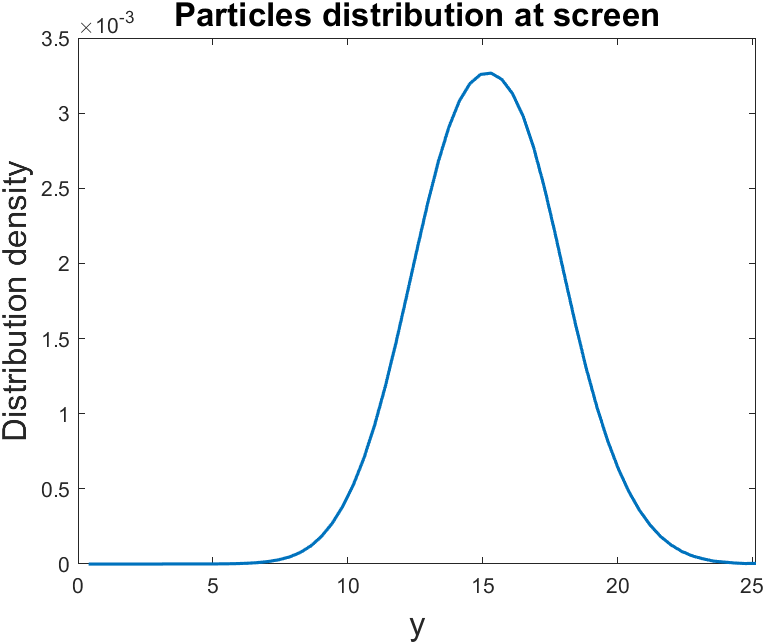

Fig. 1: Upper slit is open, lower slit is shut

We can use curve fitting toolbox to study distribution of particles at the screen when only one slit is open. Fitting to gaussian distribution is almost perfect. 

r=(1:N)*L/N;
f=rho(:,N-15);  % density of particles at the screen
%cftool         % fit f vs r to Gaussian distribution when only one slit is open

[Export Fits to the Workspace](https://www.mathworks.com/help/curvefit/generating-code-and-exporting-fits-to-the-workspace.html#bryq_ya-1) from curve fitting toolbox.

Next, consider situation when only the lower slit is open:

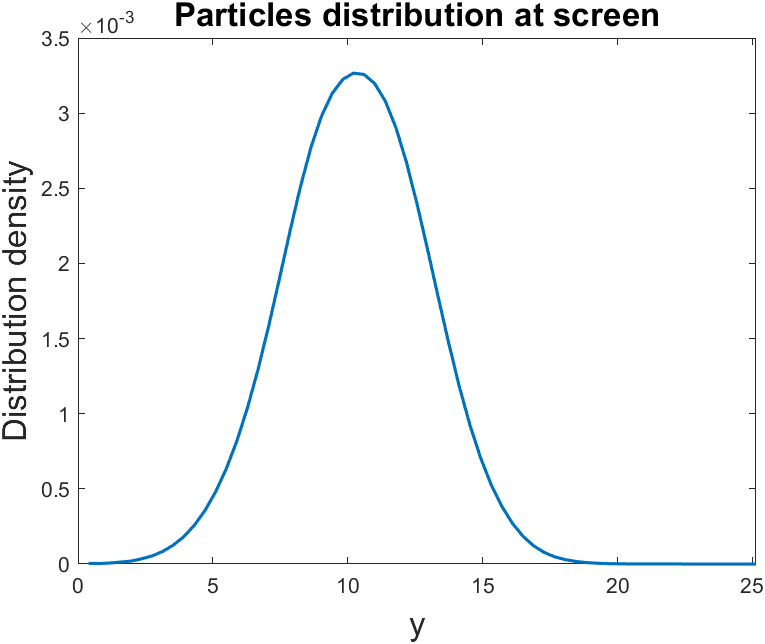

Fig. 2: Lower slit is open, upper slit is shut

Consider averaged situation, when one slit is open 50% of times while another is closed (averaged picture of the above two cases). In this case, as well, no interference fringes are observed.

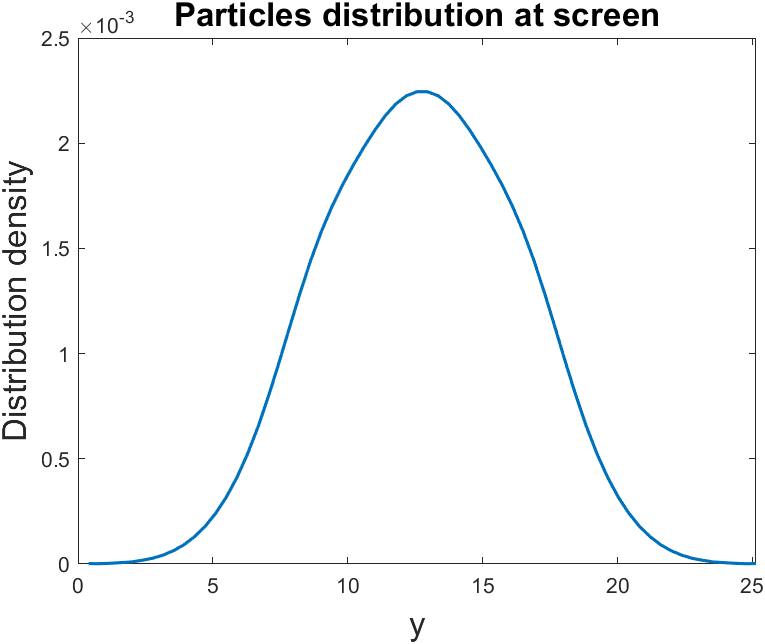

Fig. 3: Particle distrubution at the screen corresponding to the case when 50% of times only the right slit is open and other 50% of times only left. This picture is expected classically, assuming electron chooses equally randomly left or right slits to tunnel through.  

Only when both slits are open simultaneously, interference fringes are observed. Hence electron does not tunnel in either right or left slits, but in both slits simultaneously.

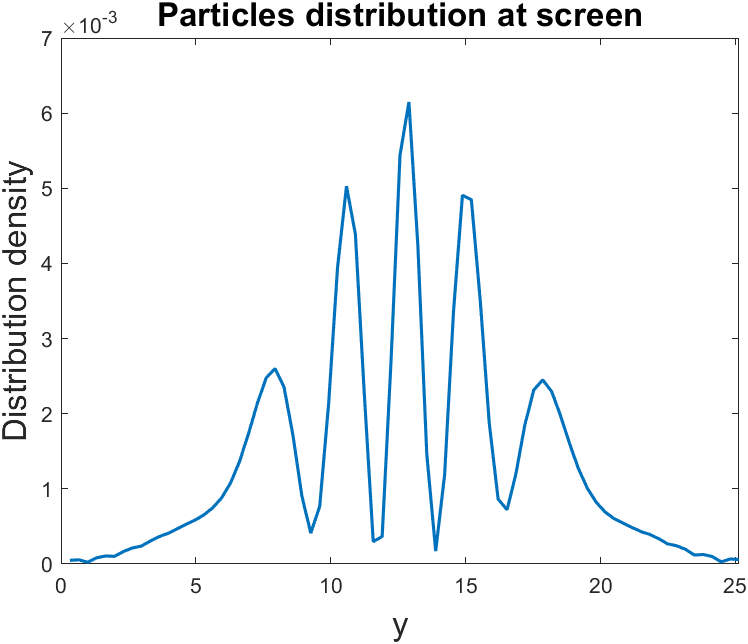

Fig. 4: Particle distribution at the screen when both slits are open and 

particle's wave-length is comparable to the distance between the slits

In Fig. 4 particle's density displays interference pattern at the screen. Waves emanating from lower and upper slits overlap, interfere and produce interference fringes (bright and dark bands caused by beams that are in and out of phase with one another). 

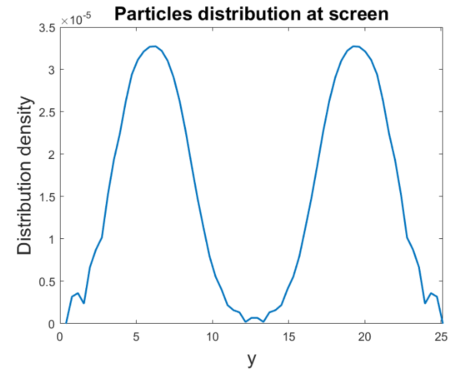

Fig. 5: Particle distribution at the screen when both slits are open, 

but distance between the slits is $\sim 2$x longer than particle's wave-length

Finally, in Fig. 5 we plot particle density at the screen for the case when the distance between the slits is  $\sim 2$x longer than particle's wave-length. In this case waves emanating from the two slits do not overlap considerably (observe the spatial separation between the two gaussians in Fig. 5) and hence no interference fringes are produced. 

## Analogy with other wave-propagation in nature: Propagation of light 

Interference results observed with matter particles (electrons, atoms, molecules) is similar to the one of the most famous experiments in classical optics, Young's double-slit experiment which shows light interference when an aperture comprises two parallel slits.

See [Simulating Yung's double slit experiment](https://www.mathworks.com/help/parallel-computing/using-fft2-on-the-gpu-to-simulate-diffraction-patterns.html) in MATLAB documentation page (devoted to using FFT on accelerated hardware - the GPU to simulate efficiently diffraction patterns).

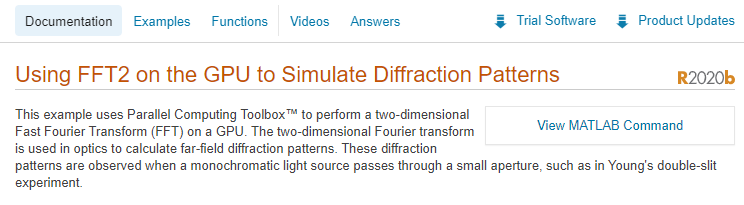

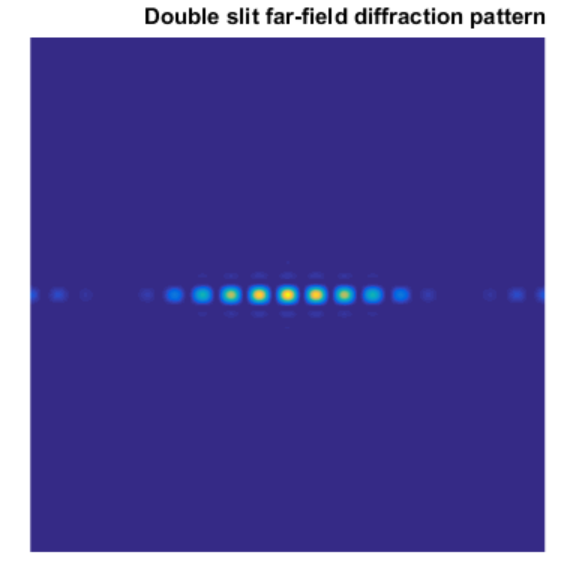

If you have GPU connected to your computer try out in MATLAB:  `>>openExample('parallel/paralleldemo_gpu_fft2')`

See [this](https://www.mathworks.com/help/pde/ug/helmholtzs-equation-on-a-unit-disk-with-a-square-hole.html) MATLAB documentation page for another scattering problem of a wave, this time a wave propagating in a 2D membrane.

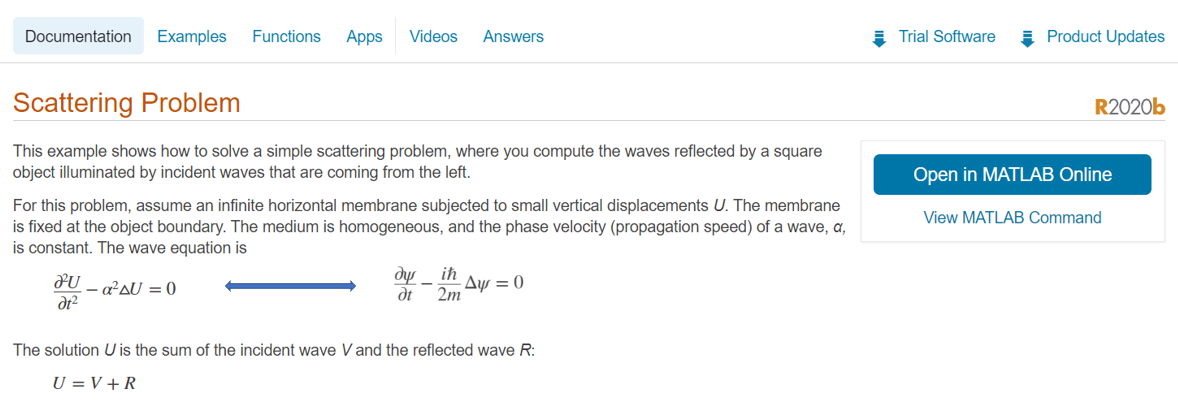

Sound propagation is also described by Helmholtz equation with $U\to p$ and $\alpha \to v_s$, where $p$ is the acoustic pressure (local deviation from the ambient pressure). Equivalently, instead of pressure one can use vector field particle velocity $\vec u= \vec \nabla p$. The latter case is directly related to electromagnetic wave propagation in space with $U\to \vec E$ and $\alpha \to c=\frac{1}{\sqrt{\mu_0 \varepsilon_0}}$. 

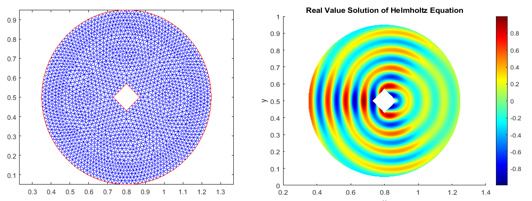

To play the movie, use the `movie(M)` command.

## Two particles in one dimension

In this section we will simulate two identical particles in one dimension. As will become clear, computationally this problem is comparable to the case studied above of one particle in two dimensions. 

First, let's review analytically case of $N_p$ identical fermions (electrons).

When Hamiltonian of the system is a direct sum of single particle Hamiltonians, the fermionic many-body eigenstates can be constructed by filling those single-particle states and antisymmetrization procedure. One can use a direct product of (orthonormal) single-particle states to obtain $N_p$-fermion normalized state,


$$(6)\quad |\alpha>=|\alpha_1,\alpha_2,...\alpha_{N_p}>=\frac{1}{\sqrt{N_p!}}\sum_P \mathrm{sign}(P)|\alpha_{P_1}>\otimes |\alpha_{P_2}>... |\alpha_{P_{N_p}}> =\frac{1}{\sqrt{N_p!}}(|\alpha_1>\otimes |\alpha_2>... |\alpha_{N_p}>-...  ),$$


where $P$ is a permutation of $N_p$ indices (sum is over all permutations, hence $N_p!$ terms are summed) and sign($P$) is a parity of permutation.

To obtain many-fermion wavefunction in coordinate representation for this case we multiply state in Eq. (6) with the direct product of $N_p$ coordinate basis states $<x_1|\otimes<x_2|...<x_{N_p}|$,

$
\Phi^{norm}_{\alpha_1,\alpha_2,...\alpha_{N_p}}(x_1,x_2,...x_{N_p})= <x_1|\otimes<x_2|...<x_{N_p}|\frac{1}{\sqrt{N_p!}}(|\alpha_1>\otimes |\alpha_2>... |\alpha_{N_p}>-...  ) $.

This wavefunction is a normalized (to unity) Slater determinant and is antisymmetric with respect to exchanging any pair of coordinates. It is as well antisymmetric with respect to exchanging any two single particle quantum states $\alpha_i \to \alpha_j$, since determinant of the matrix is antisymmetric when any two rows or two columns are exchanged. 

$\Phi^{norm}_{\alpha_1,\alpha_2,...\alpha_{N_p}}(x_1,x_2,...x_{N_p})=\frac{1}{\sqrt{N_p!}}\left| \begin{array}{cccc} \phi_{\alpha_1}(x_1)    &  \phi_{\alpha_1}(x_2) &\cdots &\phi_{\alpha_1}(x_{N_p})     \\ \phi_{\alpha_2}(x_1)   & \phi_{\alpha_2}(x_2)   &\cdots &   \phi_{\alpha_2}(x_{N_p})&  \\ 
\cdots   &  \cdots &\cdots &\cdots     \\
  \phi_{\alpha_{N_p}}(x_1)    &  \phi_{\alpha_{N_p}}(x_2) &\cdots &\phi_{\alpha_{N_p}}(x_{N_p})\end{array} \right|
$.

Alternatively we can write

$\Phi^{norm}_{\alpha_1,\alpha_2,...\alpha_{N_p}}(x_1,x_2,...x_{N_p})=  <x_1,x_2,...x_{N_p}|\alpha_1>\otimes |\alpha_2>... |\alpha_{N_p}>$,

where $|x_1,x_2,...x_{N_p}>=\frac{1}{\sqrt{N_p!}}\sum_P \mathrm{sign}(P)|x_{P_1}>\otimes |x_{P_2}>... |x_{P_{N_p}}>.$ 

Wavefunction $\Phi^{norm}_{\alpha_1,\alpha_2,...\alpha_{N_p}}$ is normalized to unity $\int \mathrm{d}x_1...\mathrm{d}x_{N_p}
|\Phi^{norm}_{\alpha_1,\alpha_2,...\alpha_{N_p}}(x_1,x_2,...x_{N_p})|^2=1, $ provided each single-particle wavefinction is normalized to unity,

$(7) \quad \int \mathrm{d}x|\phi_{\alpha_i}(x) |^2=1$, 

where $\phi_{\alpha_i}(x)=<x|\alpha_i>$. That's why we denote it with $\Phi^{norm}$.

Note, if we define a many-fermion wavefunction in a way that guarantees antisymmetry with respect to exchanging any pair of particles' coordinates even when we can not represent $|\alpha\rangle$ as a direct product of single particle states

$\Phi_{\alpha_1,\alpha_2,...\alpha_{N_p}}(x_1,x_2,...x_{N_p})=   <x_1,x_2,...x_{N_p}| \alpha>$,

then for the case when the single particle classification of states is possible $|\alpha>=|\alpha_1,\alpha_2,\cdots,\alpha_{N_p}>$, we get again the same Slater determinant, but without $1/\sqrt{N_p!}$ normalizing prefactor. This is so, since there will be $N_p!$ identical terms and $1/\sqrt{N_p!}$ prefactor squared in denominator (one $1/\sqrt{N_p!}$ from $|\alpha_1,\alpha_2,\cdots,\alpha_{N_p}>$ and another from $<x_1,x_2,...x_{N_p}|$ ) will be canceled by the nominator,


$$(8) \quad \Phi_{\alpha_1,\alpha_2,...\alpha_{N_p}}(x_1,x_2,...x_{N_p})=\sqrt{N_p!}\Phi^{norm}_{\alpha_1,\alpha_2,...\alpha_{N_p}}(x_1,x_2,...x_{N_p}) =\left| \begin{array}{cccc} \phi_{\alpha_1}(x_1)    &  \phi_{\alpha_1}(x_2) &\cdots &\phi_{\alpha_1}(x_{N_p})     \\ \phi_{\alpha_2}(x_1)   & \phi_{\alpha_2}(x_2)   &\cdots &   \phi_{\alpha_2}(x_{N_p})&  \\ 
\cdots   &  \cdots &\cdots &\cdots     \\
  \phi_{\alpha_{N_p}}(x_1)    &  \phi_{\alpha_{N_p}}(x_2) &\cdots &\phi_{\alpha_{N_p}}(x_{N_p})\end{array} \right|.

$$


Instead of unit normalization we get:

$(9) \quad \int \mathrm{d}x_1...\mathrm{d}x_{N_p}
|\Phi_{\alpha_1,\alpha_2,...\alpha_{N_p}}(x_1,x_2,...x_{N_p})|^2=N_p! 
$.

In the following we will assume many-body wavefunctions normalized to $N_p!$ as in Eq. (9).

To derive expression corresponding to two-body processes, like inter-particle interactions, it is convenient to decompose any state in a coordinate basis, 


$$|\alpha> =\int \mathrm{d}x_1...\mathrm{d}x_{N_p} \frac{1}{N_p!}|x_1,x_2,...x_{N_p}><x_1,x_2,...x_{N_p}|\alpha >.$$


Note, there is a normalization factor of $1/N_p!$ above, because when we integrate with $x_i$ over the whole space (or over (0,L) region) we repeat the same states $N_p!$ times. Let us check this explicitly for $N_p=2$, where a two-body normalized antisymmetric state is

$|\alpha>=1/\sqrt{2!}  ( |\alpha_1>\otimes |\alpha_2> - |\alpha_2>\otimes |\alpha_1> )$.


$$\int \mathrm{d}x_1 \mathrm{d}x_2 \frac{1}{2!} |x_1,x_2><x_1,x_2| \alpha> \\
=\int \mathrm{d}x_1 \mathrm{d}x_2 \frac{1}{(2!)^2}  ( |x_1>\otimes |x_2> - |x_2>\otimes |x_1> )  (<x_1|\otimes <x_2|-<x_2|\otimes <x_1| )  \frac{1}{\sqrt{2!}}( |\alpha_1>\otimes |\alpha_2> - |\alpha_2>\otimes |\alpha_1>  )\\
=\int \mathrm{d}x_1 \mathrm{d}x_2 \frac{1}{\sqrt{2!}(2!)^2}  ( |x_1>\otimes |x_2> - |x_2>\otimes |x_1> )  ( 2\phi_{\alpha_1}(x_1) \phi_{\alpha_2}(x_2)+2\phi_{\alpha_2}(x_1) \phi_{\alpha_1}(x_2)  )  \\
=\frac{1}{\sqrt{2!}2!}( 2|\alpha_1> \otimes|\alpha_2> -2|\alpha_2> \otimes|\alpha_1> )=|\alpha>. 
$$


Above we have used,  

$|\alpha_i>= \int\mathrm{d}x |x><x |\alpha_i>  =\int\mathrm{d}x \phi_{\alpha_i}(x) |x>$ for $i=1,2$`.`

Particle density operator (one-body density matrix in the first quantization picture) is defined as,


$$\hat {\rho}(r)=\sum^{N_p}_{i=1} \delta(r-\hat {r}_i).$$


Particle density in state $|\alpha>$ is,


$$\rho_{\alpha} (r)=  <\alpha|  \sum_i \delta(r-\hat {r}_i)  |\alpha>=  <\alpha|  \sum_i \delta(r-\hat {r}_i) \int \mathrm{d}x_1...\mathrm{d}x_{N_p} \frac{1}{N_p!} |x_1,x_2,...x_{N_p}><x_1,x_2,...x_{N_p}| \alpha> \\
\quad \quad =  \int \mathrm{d}x_1...\mathrm{d}x_{N_p}  \sum_i \delta(r- {x}_i) \frac{1}{N_p!} |\Psi_{\alpha}(x_1,x_2,..x_{N_p})|^2\\
\quad \quad =
 \frac{1}{N_p!}\int \mathrm{d}x_2...\mathrm{d}x_{N_p}| \Psi_{\alpha}(r,x_2,...x_{N_p}) |^2+\frac{1}{N_p!}\int \mathrm{d}x_1 dx_3...\mathrm{d}x_{N_p}| \Psi_{\alpha}(x_1,r,x_3,...x_{N_p}) |^2+\cdots\\
\quad \quad =N_p  \int \mathrm{d}x_2...\mathrm{d}x_{N_p} \frac{1}{N_p!} |\Psi_{\alpha}(r,x_2,..x_{N_p})|^2,$$


where in arriving at the last line we have used the fact that many-body wave-function describing identical fermions is antisymmetric with respect to exchanging particle coordinates and due to normalization of many-body states discussed above:$\int\mathrm{d} r \rho_{\alpha} (r)=  N_p.$

For $N_p=1$ we get a usual quantum-mechanical probability density corresponding to a single particle:

$\rho_{\alpha}(x)=|\psi_{\alpha}(x)|^2$.

For $N_p=2$ we have


$$(10) \quad \rho_{\alpha}(r)=  <\alpha|  \sum_i \delta(r-\hat {r}_i)  |\alpha>=  <\alpha|  \left(\delta(r-\hat {x}_1) + \delta(r-\hat {x}_2)\right) \int \mathrm{d}x_1\mathrm{d}x_2 \frac{1}{2} |x_1,x_2><x_1,x_2| \alpha> \\
\quad\,\,\,\,\,=\frac{1}{2} \int d x|\psi_{\alpha}(r,x)|^2+\frac{1}{2} \int d x|\psi_{\alpha}(x,r)|^2=  \int d x|\psi_{\alpha}(r,x)|^2.$$


For the last expression in Eq. (10) we made an assumption that we are dealing with two identical particles, hence $\psi_{\alpha}(r,x)=\pm \psi_{\alpha}(x,r)$.

### Statics: eigenvalue problem

We first start simulating two particles in 1D box of size $L$.

L = 2;  
N = 64;  
x = linspace(0, L, N).'; 
dx = x(2) - x(1); 
 
e    = ones(N,1);       
Lap_1D  = spdiags([e -2*e e],[-1 0 1],N,N) / dx^2;  
V_add=kron(heaviside(x-L)+heaviside(0-x),e)+kron(e,heaviside(x-L)+heaviside(0-x));
K_1=-1/2*kron(Lap_1D,speye(N)); % matrix corresponding to kinetic energy of first particle
K_2=-1/2*kron(speye(N),Lap_1D); % matrix corresponding to kinetic energy of second particle

H=K_1+K_2+100*sparse(diag(V_add));              
[V,E] = eigs(H,15,'smallestreal'); % find eigs.
[E,ind] = sort(diag(E));       % convert diagonal matrix E to a column vector and sort low to high
V = V(:,ind);                  % rearrange corresponding eigenvectors.
format long
E % show energies 

[X,Y]=meshgrid(x);
surf(X,Y,reshape(-V(:,1),N,N)) % ground state is symmetric when exchanging r1 and r2 (bosonic state)
surf(X,Y,reshape(V(:,2)+V(:,3),N,N)) % is antisymmetric when exchanging r1 and r2 (fermionic state has a nodal line for r1=r2, Pauli exclusion)
surf(X,Y,reshape(V(:,2)-V(:,3),N,N)) % is symmetric with exchange between r1 and r2 (bosonic state)

g=1; %positive sign means repulsion, negative signe means attraction
a=1;
U=heaviside(a- abs(kron(x,ones(N,1)) -kron(ones(N,1),x))  ); %short-range potential between particles
H=K_1+K_2+1000*sparse(diag(V_add))+ g*sparse(diag(U));

[V,E] = eigs(H,15,'smallestreal'); % find eigs.
[E,ind] = sort(diag(E));       % convert diagonal matrix E to a column vector and sort low to high
V = V(:,ind);                  % rearrange corresponding eigenvectors.
format long
E % show energies

surf(X,Y,reshape(-V(:,1),N,N)) % ground state is symmetric when exchanging r1 and r2 (bosonic state) for both repulsion and attraction
surf(X,Y,reshape(V(:,2),N,N)) % first excited state for repusion is fermionic and for attracive case is bosonic
surf(X,Y,reshape(V(:,3),N,N)) % second excited state is bosonic for repulsion and fermionic for attraction 

Note ground state $V(:,1)$ is symmetric with respect to exchange of $r_1$ and $r_2$. For the case of $g=0$ (non-interacting particles), first two excited states ( eigenvectors $V(:,2)$ and $V(:,3)$) as returned by computer have no definite  parity with respect to exchange of $r_1$ and $r_2$. We have to form their linear combinations, $V(:,2)\pm V(:,3)$, to extract fermionic and bosonic  two-particle eigenstates. Degeneracy between the different parity eigenstates is a common feature of the spectrum of non-interacting particles and results from the fact that two-body states are always represented as a product of single-particle states.  

Let's turn on (small) interaction $g\neq 0$ between particles. For $g>0$ (repulsive interaction) we see that first excited state is fermionic, while for $g<0$ (attractive interaction) first excited state is bosonic. For very strong repulsive interaction ground state is (almost) twofold degenerate (bosonic and fermionic states have nearly same energy and it is the lowest energy) and both ground states have node at $r_1=r_2$.

### Dynamics: scattering problem 

Below we will simulate time dependent problem of scattering of two interacting particles in 1D, prepared initially as two gaussian wavepackets. We will consider non-interacting, attractively interacting, and repulsively interacting particles. The influence of the particle statistics on the energy of the system will be discussed at the end.

L = 16*pi;                 % 1D segment length 
N = 40;                    % No of points 
x = linspace(0,L,N).';     % Coordinate x vector, column
dx=x(2)-x(1);

 dk = 2*pi/L;              % Momentum step
 km = N*dk;                % Momentum limit
 kx = linspace(0,+km,N).'; % Momentum vector


psi1 = exp(-0.25*( x-L/5).^2).*exp(3i*kx(5)*x);      % this is psi_{alpa_1}
psi1 = psi1(:) / sqrt(psi1(:)' * psi1(:) );          % normalize to unity single particle state Eq. (7)
psi2 = exp(-0.25*( x-4*L/5).^2 ).*exp(-3i*kx(5)*x);  % this is psi_{alpa_2}
psi2 = psi2(:) / sqrt(psi2(:)' * psi2(:));           % normalize to unity single particle state Eq. (7)
psi=kron(psi1,psi2)-kron(psi2,psi1); % antisymmetrized wavefunction for fermions, Eq. (8) for Np=2 case
% this is a Slater determinant for 2 particles normalized to Np!=2 in this case, as in Eq. (9).
% for bosons symmetrization is in order: psi_b=kron(psi1,psi2)+kron(psi2,psi1); 
% for non-identical particles uncomment a line below
%psi=sqrt(2)*kron(psi1,psi2);

Lap = (diag(ones((N-1),1),-1) - 2*diag(ones(N,1),0) + diag(ones((N-1),1), 1)) / (dx^2);
Lap(1,   1) = 0; Lap(  1, 2) = 0; Lap(2, 1) = 0;
Lap(N, N-1) = 0; Lap(N-1, N) = 0; Lap(N, N) = 0; 

g=3;  % positive g corresponds to repulsion
H   = -(1/2)*(kron(Lap,eye(N))+kron(eye(N),Lap))+g*heaviside(10-abs(diag(kron(x,ones(N,1)))-diag(kron(ones(N,1),x))));
% Interparticle interaction is modeled as a soft-core step-like potential.
% If particles are within the distance of 10 or less they feel constant interaction potential g.


%psi'*H*psi/(psi'*psi) % expectation value of energy in state |psi>
% Parameters for computing psi at different times 0 < t < TF.
NT = 150;                % Number of time steps.
TF =16;                  % Stopping time     
t  = linspace(0,TF,NT);  % time vector
dt = t(2) - t(1);        % time step
hbar = 1;

Evolution_Operator = expm(-1i * H * dt / hbar); % time-evolution operator.
   
for jj = 1:NT   % Time index for loop.
    psi=psi(:); % reshape back to column after each loop
    psi = Evolution_Operator*psi;   % Calculate psi(t+\Delta t) from psi(t)
    % psi'*H*psi/(psi'*psi)
    psi=reshape(psi,N,N);
    
    rho = diag(psi'* psi+psi*psi')/2; % this is a more generic form for single-particle density valid as well for the case of non-identical particles 
    %rho=diag(psi'* psi); % this form of single-particle density can be used only for identical particles (fermions or bosons)
    %sum(rho) % uncomment to monitor that density integrates to number of particles

    plot(x, rho);
    axis([0 L 0 0.3]);
    hold off
    drawnow
end

## Exercise

Consider scattering of: 2 identical fermions (take for initial state antisymmetrized wavefunction), then 2 identical bosons (symmetrized wavefunction) and finally 2 non-identical, but equal mass particles and determine which energies are lower for the case of fermions, bosons or non-identical particles. In all cases for single particle states at $t=0$ take same states: two launched Gaussian wavepackets with some overlap and consider non-interacting as well as interacting cases. If wavepakets corresponding to two particles are far apart so that initially they practically do not overlap, energy should not depend on the statistics of the particles. Observe when particles in initial state are close to each other, energy of fermions for attractive interaction and non-interacting case (as well as very weakly repulsive case) is the highest (Pauli pressure), whereas energy of bosons is the lowest (Bose enhancement). For (not very weak) repulsion, energy of fermions is the lowest (antisymmetrized wavefunction has a node when positions of electrons coincide), whereas energy of bosons is the highest.

% to run this section without error, run first a section just above it 
psi1 = exp(-0.25*( x-L/5).^2).*exp(1i*kx(5)*x);      % this is psi_{alpa_1}
psi1 = psi1(:) / sqrt(psi1(:)' * psi1(:) );          % normalize to unity single particle state
psi2 = exp(-0.25*( x-L/5).^2 ).*exp(-1i*kx(5)*x);    % this is psi_{alpa_2}
psi2 = psi2(:) / sqrt(psi2(:)' * psi2(:));           % normalize to unity single particle state
psi_b=kron(psi1,psi2)+kron(psi2,psi1);    % symmetrized two-body wavefunction        
psi_f=kron(psi1,psi2)-kron(psi2,psi1);    % antisymmetrized tow-body wavefunction  
psi_12=sqrt(2)*kron(psi1,psi2);           % two-body wavefunction of non-identical particles     
psi_21=sqrt(2)*kron(psi2,psi1);           % two-body wavefunction of non-identical particles

g=0.03;  
H = -(1/2)*(kron(Lap,eye(N))+kron(eye(N),Lap))+...
g*heaviside( 10 - abs(  diag( kron(x,ones(N,1)) ) - diag( kron(ones(N,1),x)) ));

E_b=psi_b'*H*psi_b/(psi_b'*psi_b)         % energy for two bosons case
E_f=psi_f'*H*psi_f/(psi_f'*psi_f)         % energy for two fermions case
E_12=psi_12'*H*psi_12/(psi_12'*psi_12)    % energy of non-identical particles
E_21=psi_21'*H*psi_21/(psi_21'*psi_21)    % energy of non-identical particles

Claim: 

If initial two-body coordinate wavefunction is symmetric/ antisymmetric with respect to $x_1\leftrightarrow x_2$, $\psi(x_1,x_2,0)= \pm \psi(x_2,x_1,0)$, it will remain symmetrc/ antisymmetric after time evolution as well $\psi(x_1,x_2,t)= \pm \psi(x_2,x_1,t)$.

Proof:

2-body Hamiltonian (in any dimension) corresponding to system of identical particles (and hence invariant with respect to permuting coordinates of particles) has eigenstates of definite parity with respect to exchanging particles' coordinates: energy eigenstates, solutions of 2-body time-independent Schrodinger equation, are either symmetric or antisymmetric (in the case of degenerate energy eigenstates one can always form linear combinations of those states that have definite parity). Let's consider a state at time $t$=0 which is antisymmetric: 

$(11) \quad \psi (x_1,x_2 ,0)   =\sum_E  \psi_E(x_1,x_2)\langle \psi_E  |\psi(0)\rangle=\sum_E  \psi^-_E(x_1,x_2)\langle \psi^-_E  |\psi(0)\rangle$,

where $\psi^-_E$ are energy eigenstates of the system that are antisymmetric with respect to $x_1\leftrightarrow x_2$, $\psi^-_E(x_1,x_2)=-\psi^-_E(x_2,x_1)$. For any $t$ we have:

$ \psi( x_1,x_2,t)   =\sum_E e^{-i E t / \hbar} \psi^-_E(x_1,x_2)  \langle \psi^-_E  |\psi (0)\rangle$.

Hence if $\psi(x_1,x_2,0)=-\psi(x_2,x_1,0)$ then $\psi(x_1,x_2,t)=-\psi(x_2,x_1,t)$ for any $t$ .

Similarly, it can be shown that if  $\psi(x_1,x_2,0)=\psi(x_2,x_1,0)$, then for any time $\psi(x_1,x_2,t)=\psi(x_2,x_1,t)$.

## Appendix: Two interacting bosons in one dimension: calculating two-body scattering length for [Lieb-Liniger model](https://en.wikipedia.org/wiki/Lieb%E2%80%93Liniger_model) (bosons with contact delta-function interaction)

In this appendix we will present a pedagogical derivation of two-body problem in 1D with the aim to show how to extract the scattering length analytically in 1D.

In the case when inter-particle interaction depends only on relative coordinate of particles, calculations are simplified when passing to center-of-mass and relative coordinates. Center-of-mass motion is equivalent to motion of free particle with a mass equal to a mass of two particles, while relative motion is similar to a scattering of a single particle (with a reduced mass) from a fixed potential (e.g. barrier or well).

Consider scattering potential of a finite range $R$, $V(r)=\pm V\Theta(R/2-|r|)$, where $V>0$ is assumed and + sign corresponds to barrier and - sign to well.

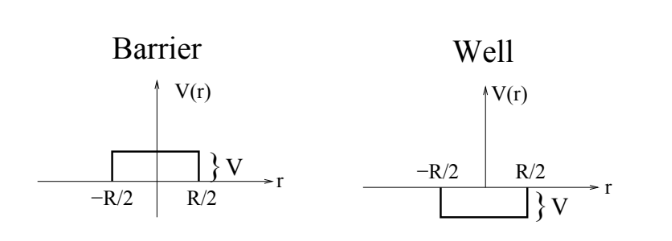

Inter-particle potentials for "barrier" and "well" step-like interactions

$V(r)=\pm V\Theta(R/2-|r|)$, where r is a relative coordinate

One-dimensional scattering length $a_{1D}$ is defined from the scattering phase shift as,


$$\delta_k=-\frac{\pi}{2}-a_{1D}k+O(k^2),$$


where relative momentum $k\to 0$, corresponding to low energy scattering. Alternatively,


$$a_{1D}=\lim_{k\to 0}\frac{\cot\delta_k}{k}.$$


For definition of scattering length in 2D and 3D see [this paper](https://arxiv.org/pdf/0812.4054.pdf).

For scattering off the potential Barrier

$a_{1D}=R(1-\frac{\coth {\sqrt{\frac{Vm}{2\hbar^2}}R}}{\sqrt{\frac{Vm}{2\hbar^2} }R})$.

One can check that dimension of $\sqrt{\hbar^2 /(Vm)}$is the same as that of $R$, length, since dimension of $\sqrt{1 /(Energy*mass)}$  is inverse momentum. 

Let's plot scattering length corresponding to "barrier" potential as a function of $V$.

V=linspace(0.4,10,100);
R=1;
hbar=1;
m=1;
a=   R * (1   -  coth(R* sqrt(V*m/(2*hbar^2)))./ ( R*sqrt(V*m/(2*hbar^2)) ));
plot(V,a)
yline(0)
yline(1,'linestyle','--')
xline(2*36*hbar^2/(25*R^2*m))
xlabel('V, barrier height')
ylabel('a_{Barrier}')
axis([0 10 -4 4])
title('Scattering length corresponding to a barrier scattering')
hold off

$a_{1D}<0$` for `$\sqrt{mV}R/\sqrt{2}\hbar<6/5$.

`For `$V\to \infty$`, `$a_{1D}\to R$`. `

For scattering off the potential well we have,


$$a_{1D}=R(1+\frac{\cot {\sqrt{\frac{Vm}{2\hbar^2}}R}}{\sqrt{\frac{Vm}{2\hbar^2} }R})$$


V=linspace(0.1,90,1000);
R=1;
hbar=1;
m=1;
a=   R *  (1   +  cot(R* sqrt(V*m/(2*hbar^2)))./ ( R*sqrt(V*m/(2*hbar^2)) ));
plot(V,a)
axis([0 90 -20 20])
xlabel('V, well depth')
ylabel('a_{well}')
yline(0)
title('Scattering length corresponding to scattering off a potential well')
% syms R h m V
% a=   R *  (1   +  cot(R* sqrt(V*m/(2*h^2)))./ ( R*sqrt(V*m/(2*h^2)) ))

Resonances are supported by well potential. Each time bound state enters the well, the scattering length diverges. The interaction range though is always short-range: $R$.

Below we will derive scattering length for the Lieb-Liniger model (one-dimensional bosons interacting with each other with delta function contact interaction, and supporting one and only one bound state for any attraction $g<0$) with interaction constant $g$ (for both signs of $g$), 


$$a_{LL}=-\frac{2 \hbar^2}{gm}.$$


#### Two boson scattering and bound states of Lieb-Liniger model

Hamiltonian describing the many-body Lieb-Liniger model looks,


$$H_{LL}=-\frac{\hbar^2}{2m}\sum_{i=1}^{N_p}\frac{\partial^2}{\partial x^2_i}+g \sum_{i<j} \delta(\hat x_i-\hat x_j).$$


We will consider two-body problem $N_p=2$. First we introduce the coordinate for the center of mass $X=(x_1+x_2)/2$ and the relative coordinate $r=x_1-x_2$. The center of mass will move like a free particle of mass $2m$, and hence normalization to unity of wavefunction $\Psi(x_1,x_2)$ is only possible in the finite volume. In the following we will not need explicitly normalized wavefunction, but we note that in general we can use the following normalization,


$$\int_{-L/2}^{L/2}\int_{-L/2}^{L/2} \mathrm{d} x_1 \mathrm{d} x_2   |\Psi(x_1,x_2)|^2=1,\quad 
\int_{-L/2}^{L/2}\int_{-L/2}^{L/2} \mathrm{d} x_1 \mathrm{d} x_2  =L^2.$$


After the change to the center of mass and relative coordinates (it has unit Jacobian) we will have,


$$\int_{-L/2}^{L/2}  \mathrm{d} X   \int_{-L+2|X|}^{L-2|X|}  \mathrm{d} r     |\Psi(X,r)|^2=1,\quad  \int_{-L/2}^{L/2}  \mathrm{d} X   \int_{-L+2|X|}^{L-2|X|}  \mathrm{d} r    =L^2 .$$


## 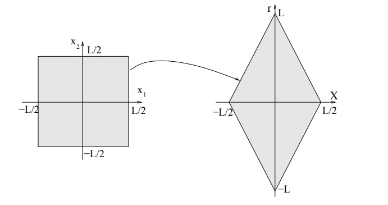

Change of area under change of coordinates to relative and center of mass 

Alternative way is to integrate over the triangle $x_1>x_2$ and double,


$$\int_0^L  \mathrm{d} x_1 \int_0^L  \mathrm{d} x_2= 2\int_0^L   \mathrm{d} r  \int_0^{L-r} \mathrm{d} X.$$


In the new coordinates we have,

$\frac{\partial^2}{\partial x^2_{1,2}}= \frac{1}{4}\frac{\partial^2}{\partial X^2}\pm \frac{\partial^2}{\partial X\partial r}+ \frac{\partial^2}{\partial r^2} $,

thus 


$$\frac{\partial^2}{\partial x^2_1}+\frac{\partial^2}{\partial x^2_2}= \frac{1}{2}\frac{\partial^2}{\partial X^2}+2 \frac{\partial^2}{\partial r^2}.$$


We have to solve the following 2-body Schrödinger equation,

$\Big[  -\frac{\hbar^2}{4m}\frac{\partial^2}{\partial X^2} -\frac{\hbar^2}{m} \frac{\partial^2}{\partial r^2}    +g\delta(r) \Big] \Psi(X,r) = E\Psi(X,r)$.

We will look for the bound states solution (neglecting the normalization condition for simplicity),


$$\Psi(X,r)= e^{iPX}e^{-|r|/a}.$$


$P$ is a total momentum of two-body system, which is a good quantum number. Since the center of mass motion decouples from the relative one, and center of mass moves like a free particle, we can put $P=0$ and keep in mind, that for finite $P$ the contribution to the energy will be $P^2/4m$. We have the following relations:


$$-\frac{\hbar^2}{m} \frac{\partial^2}{\partial r^2}e^{-|r|/a}= \frac{\hbar^2}{m} \frac{\partial}{\partial r}(e^{-|r|/a} \frac{sign(r)}{a})=- \frac{\hbar^2}{m}e^{-|r|/a}\frac{sign^2(r)}{a^2}+\frac{\hbar^2}{m}e^{-|r|/a}\frac{2\delta(r)}{a}.$$


Plugging this in 2-body Schrödinger equation we obtain for $P=0$,


$$- \frac{\hbar^2}{m}e^{-|r|/a}\frac{1}{a^2}+\frac{\hbar^2}{m}e^{-|r|/a}\frac{2\delta(r)}{a}+g\delta(r) e^{-|r|/a}=E_be^{-|r|/a}.$$


Hence, $a=-\frac{2\hbar^2}{gm}$ and bound state only exist for $a>0$, corresponding to attraction $g<0$. Bound state energy, binding energy $E_b=-\frac{\hbar^2}{ma^2}$ and is negative. If we assume finite $P$ we get, $E=\frac{P^2}{4m}+E_b$. The bound state wavefunction has a cusp at $r=0$, its first derivative has a jump ($\sim \mathrm{sign} (r)$) because the potential is singular (delta-function). For finite potentials (e.g. Lorentzian regularization) wave-function and its first derivative are continuous.

Note, two identical fermions can not form the bound state in attractive LL model, since this only available bound state is symmetric (s-wave) for $x_1\leftrightarrow x_2$, $r\to -r$! Contact interaction does not support antisymmetric (p-wave) bound state due to Pauli principle.

 % attractive contact potential
m=1;
hbar=1;
r=linspace(-4,4,1000).';
for g=-2:-3:-8
    a=-2*hbar^2/(g*m);
    psi=exp(-abs(r)/a)/2/a; % normalized wavefunction
    plot(r,psi)
    xlabel('r (relative coordinate)')
    ylabel('Wavefunction of relative motion')
    hold on    
end
legend({'g=-2','g=-5','g=-8'})
title('Bound-state wavefunction for different values of g')
hold off

Now we look for the scattering states solution of 2-body Schrödinger equation. Since the interaction is only local, at far distances we expect the solution to be given by some combination of plane waves, explicitly symmetric under exchange of coordinates of bosons,


$$\Psi(x_1,x_2)=\Theta(x_1-x_2)\Big[  e^{i(\frac{p_1x_1}{\hbar}   +\frac{p_2x_2}{\hbar} )}+s(p_1-p_2,g)  e^{i(\frac{p_2 x_1}{\hbar}   +\frac{p_1 x_2}{\hbar} )}      \Big]\\
\quad \quad \quad+(1- \Theta(x_1-x_2))\Big[ s(p_1-p_2,g)    e^{i(\frac{p_1x_1}{\hbar}   +\frac{p_2x_2}{\hbar} )}+ e^{i(\frac{p_2 x_1}{\hbar}   +\frac{p_1 x_2}{\hbar} )}      \Big]$$


In the center of mass and relative coordinates this will look,


$$\Psi(X,r)=e^{iPX}\Big[\Theta(r)\psi(r)+\Theta(-r)\psi(-r) \Big],$$


where $\psi(r)= e^{i\frac{p r}{\hbar} }+s(2p,g)    e^{-i\frac{p r}{\hbar} }$, thus


$$\Psi(X,r)/e^{iPX}=\Theta(r)\Big[  e^{i\frac{p r}{\hbar} }+s(2p,g)    e^{-i\frac{p r}{\hbar} }     \Big]
+(1- \Theta(r))\Big[ s(2p,g)      e^{i\frac{p r}{\hbar} }+  e^{-i\frac{p r}{\hbar} }    \Big]$$


where $1- \Theta(r)=\Theta(-r)$, $p=(p_1-p_2)/2$ and we have introduced two-body s-matrix. The energy of the scattering state is,


$$E=\frac{p^2_1}{2m}+ \frac{p^2_2}{2m}=\frac{P^2}{4m}+ \frac{p^2}{m}.$$


For simplicity we put $P=0$ (we go to the center of mass inertial system) and have (using $\delta (r) f(r)=\delta(r)f(0)$),


$$\frac{\partial \Psi}{\partial r}= \delta(r)[1+s]-\delta(r)[s+1]
+\Theta(r) \Big[ \frac{ip}{\hbar}e^{ipr/\hbar}  -\frac{ip}{\hbar}se^{-ipr/\hbar}   \Big] \\
\quad\quad+\Big(1-\Theta(r) \Big) \Big[ \frac{ip}{\hbar}se^{ipr/\hbar}  -\frac{ip}{\hbar}e^{-ipr/\hbar}   \Big]$$


and for two-body s-matrix we get the equation,


$$g\delta(r)[1+s]+\frac{2\hbar^2 }{m}\delta(r)\frac{ip}{\hbar}[1-s]=0.$$


leading to,


$$s=s(2p,g)=\frac{2p-i\frac{m}{\hbar}g}{2p+i\frac{m}{\hbar}g}.$$


To make contact with scattering phase shift the two-body s-matrix we represented as,

$s=e^{\ln {\frac{p-i\frac{m}{2\hbar}g}{p+i\frac{m}{2\hbar}g}}}$.

using $\arctan (-x)= \frac{i}{2}\ln{ \frac{1-ix}{1+ix}}$ we can represent s-matrix as

$s= e^{-2i\arctan mg/(2 \hbar p)}=e^{2i\delta_p}$.

where we introduced scattering phase shift, $\delta_p= -\arctan \Big( mg/ 2\hbar p\Big).$ Using $\cot (\arctan x)=1/x$ we obtain,


$$\cot \delta_p=-\frac{2 p\hbar}{mg} \to  \frac {\cot \delta_p}{p}= -\frac{2 \hbar}{mg}.$$


The quantity $\hbar \frac {\cot \delta_p}{p}$ has dimension of length and it is called a scattering length, which exist independent of sign of $g$,


$$a=\hbar \frac {\cot \delta_p}{p}=-\frac{2 \hbar^2}{mg}.$$


For attractive interactions scattering length obtained from scattering states coincides with the correlation length (width) of the bound state.

It is interesting to note, that for $p_1\to p_2$ we have $p\to 0$, and $s\to -1$, $\delta_p \to -\pi/2$ (last limit holds for $g>0$) hence the scattering state vanishes. This is a fermionization property of 1D Bose gas. This is in a drastic contrast to 3D case, where $\delta_k\sim -ka_{3D}$ for $k\to 0$.

## Conclusion

We covered two computationally similar, but conceptually different problems: simulation of dynamics of a quantum particle in 2D and simulation of scattering of two interacting particles off each-other in 1D.

Live script can be used for integrating technical computing into quantum mechanics lectures by educators. It can also be used by physics or chemistry students, for learning fundamentals of quantum mechanics with the help of computing. 

## References

[1] T. Young, “Experimental Demonstration of the General Law of the Interference of Light,”* Philosophical Transactions of the Royal society of London* 94, 1 (1804).

[2] C. Jonsson, “Elektroneninterferenzen an mehreren künstlich hergestellter Feinspalten”, *Zeitschrift fur Physik* 161, 454 (1961). 

[3] [M. Arndt, et al., Nature 401, 680 (1999).](https://www.nature.com/articles/44294)

function cwd()
    % Get the filename of the active document in the Editor or Live Editor
    filename = matlab.desktop.editor.getActiveFilename(); 
    % Extract the path from the filename
    path = fileparts(filename);
    % Change current working directory
    cd(path);
end